data = readtable("../Data/ENB2012_data.xlsx");

Headers = [
    "Relative Compactness"
    "Surface Area"
    "Wall Area"
    "Roof Area"
    "Overall Height"
    "Orientation"
    "Glazing Area"
    "Glazing Area Distribution"
    "Heating Load"
    "Cooling Load"];

data.Properties.VariableNames = Headers;
M = table2array(data);

X = [ones(size(M,1),1), M(:,1:8)];

y = M(:,9);

Lasso regression can be implemented using coordinate descent and solved for various regularization strengths. It can be seen how the norm of beta can decrease significatively, while the RMSE remains practically constant. For big enough regularization strengths, the RMSE will start to rise. The axes are relevant, as the changes both in RMSE and Norm are not too big.

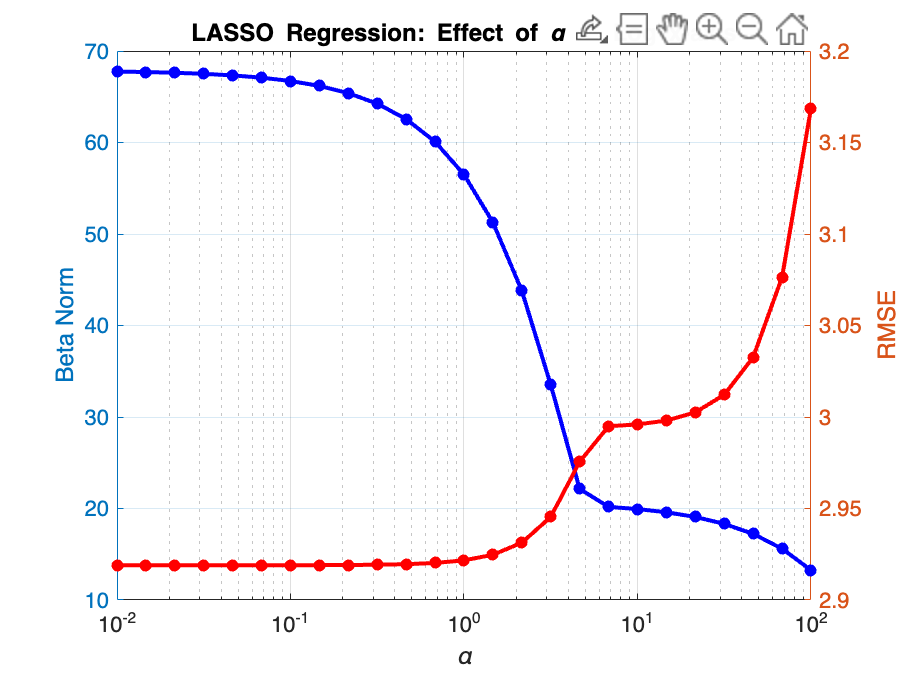

n = 25;
alpha = logspace(-2, 2, n);
RMSE = zeros(n,1);
NormBeta = zeros(n,1);
AllBeta = zeros(length(X(1,:)), n);

for i = 1:n
    [beta, intercept] = simple_lasso(X, y, alpha(i));
    
    betap = beta;
    NormBeta(i) = norm(beta); % Not penalize intercept
    beta(1) = intercept;
    
    AllBeta(:, i) = beta;
    
    RMSE(i) = sqrt(1/length(y) * sum((y - X * beta).^2));
end

figure();
yyaxis left
semilogx(alpha, NormBeta, '-o', ...
    'LineWidth', 2, ...
    'MarkerSize', 4, ...
    'MarkerFaceColor', 'b', ...
    'Color', 'b');
ylabel('Beta Norm', 'FontSize', 11)

yyaxis right
semilogx(alpha, RMSE, '-o', ...
    'LineWidth', 2, ...
    'MarkerSize', 4, ...
    'MarkerFaceColor', 'r', ...
    'Color', 'r');
ylabel('RMSE', 'FontSize', 11)

grid on
box on
xlabel('\alpha', 'FontSize', 11)
title('LASSO Regression: Effect of \alpha — Log x-axis', ...
    'FontSize', 14, 'FontWeight', 'bold')
set(gca, 'FontSize', 11)

It can be seen how LASSO penalties also allow for a substantial decrease in coefficient size, while retaining moderately similar RMSE. It can also be seen how coefficient size decreases as regularization strength increases. Due to the coefficients having different scales, its normalized coefficient with respect to its max value is shown. It can be intuitively understood that as regularization strength increases, only the most relevant features remain, while the least relevant ones decrease in magnitude.

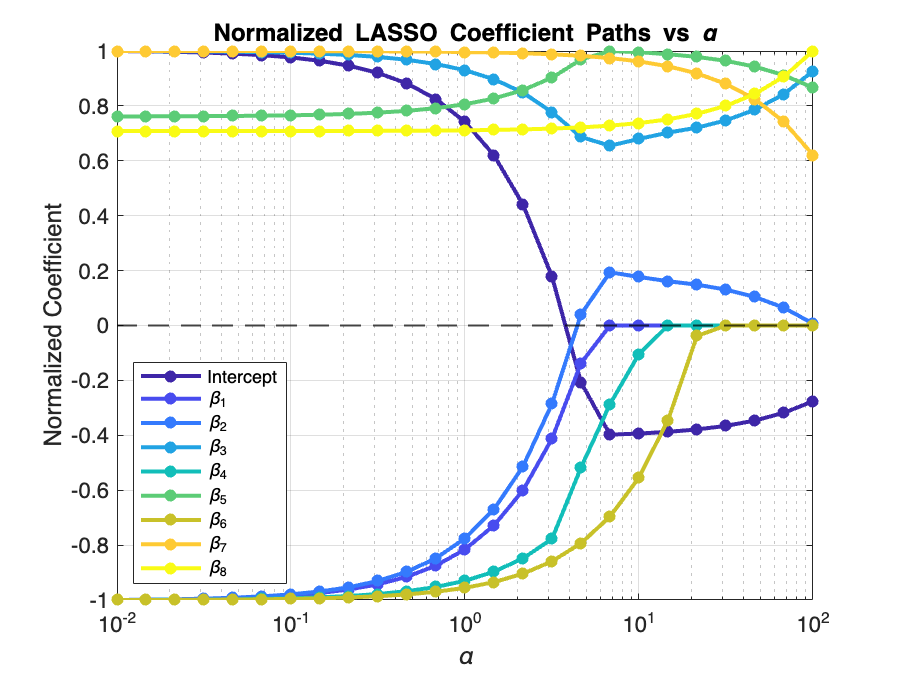

AllBetaNorm = AllBeta ./ max(abs(AllBeta), [], 2); % row-wise normalize

figure();
hold on
colors = parula(size(AllBetaNorm, 1));
for j = 1:size(AllBetaNorm, 1)
    semilogx(alpha, AllBetaNorm(j, :), '-o', ...
        'LineWidth', 2, ...
        'MarkerSize', 4, ...
        'MarkerFaceColor', colors(j, :), ...
        'Color', colors(j, :));
end
yline(0, 'k--', 'LineWidth', 1)
grid on; box on
xlabel('\alpha', 'FontSize', 11)
ylabel('Normalized Coefficient', 'FontSize', 11)
title('Normalized LASSO Coefficient Paths vs \alpha', ...
    'FontSize', 14, 'FontWeight', 'bold')
set(gca, 'FontSize', 11)
legendLabels{1} = 'Intercept';
for j = 2:size(AllBeta, 1)
    legendLabels{j} = sprintf('\\beta_%d', j-1);
end
legend(legendLabels, 'Location', 'southwest', 'FontSize', 9)
set(gca, 'XScale', 'log')
hold off